table = xlsread('D:\练习\table\2021-7-20.xls',2);
disp(table)

   1.0e+03 *

  1 至 12 列

    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    1.9130       NaN    1.9450       NaN    1.9200       NaN    2.2050       NaN    2.2600       NaN    2.3020       NaN
    0.0051       NaN    0.0032       NaN    0.0067       NaN    0.0034       NaN    0.0024       NaN    0.0041       NaN
    0.0219       NaN    0.0200       NaN    0.0268       NaN    0.0277       NaN    0.0234       NaN    0.0227       NaN
    0.0248       NaN    0.0257       NaN    0.0268       NaN    0.0280       NaN    0.0304       NaN    0.0300       NaN
    0.

w1 = table(2:16,1:16);
w2 = table(18:32,1:16);
w3 = table(34:48,1:16);
w4 = table(50:64,1:16);
disp(w4)

        Var1             Var2     
    _____________    _____________

    [1x15 double]    [1x16 double]



% p = pchip(x,y,new_x) 分段三次埃尔米特插值
x1=1:2:15;
y1=table(5,1:2:15);
% new_x1=2:2:16;
% p1 = pchip(x1,y1,new_x1);
% disp(p1);
new_px1=1:0.2:16;
p1 = pchip(x1,y1,new_px1);

x2=1:2:15;
y2=table(6,1:2:15);
% new_x2 = 2:2:16;
% p2 = pchip(x2,y2,new_x2);
% disp(p2);
new_px2=1:0.2:16;
p2 = pchip(x2,y2,new_px2);

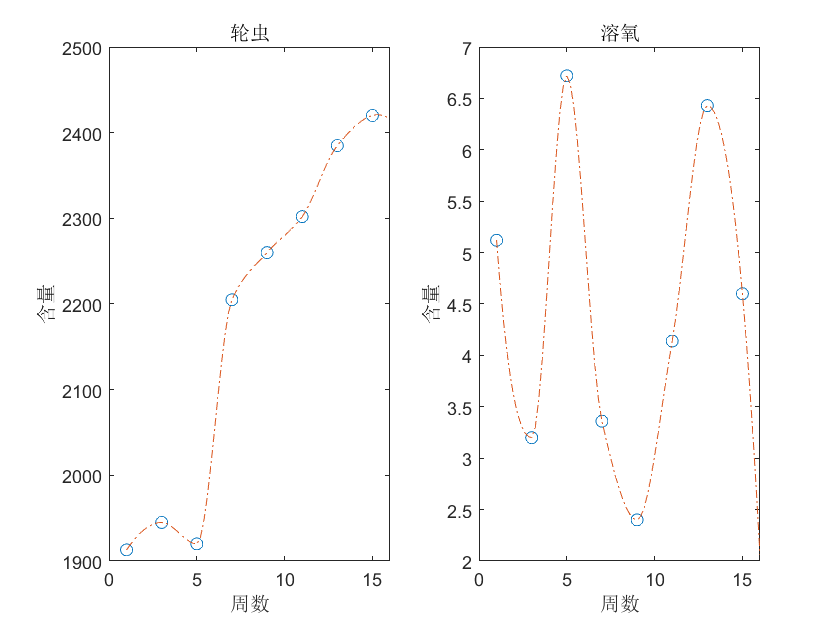

subplot(1,2,1)
plot(x1,y1,'o',new_px1,p1,'-.')
xlabel('周数');ylabel('含量');
title('轮虫');
subplot(1,2,2)
plot(x2,y2,'o',new_px2,p2,'-.')
xlabel('周数');ylabel('含量');
title('溶氧');

% x=1:2:15;%x轴上的数据，第一个值代表数据开始，第二个值代表间隔，第三个值代表终止
% for i=1:15
%     subplot(4,4,i);
%     y=w1(i,:);
%     plot(x,y); %线性，颜色，标记
%     xlabel('周数');ylabel('含量');
% end